Read the clip and play it

[y,Fs] = audioread("chord1.mp3");
player = audioplayer(y, Fs);
play(player);

Plot the signal `y`

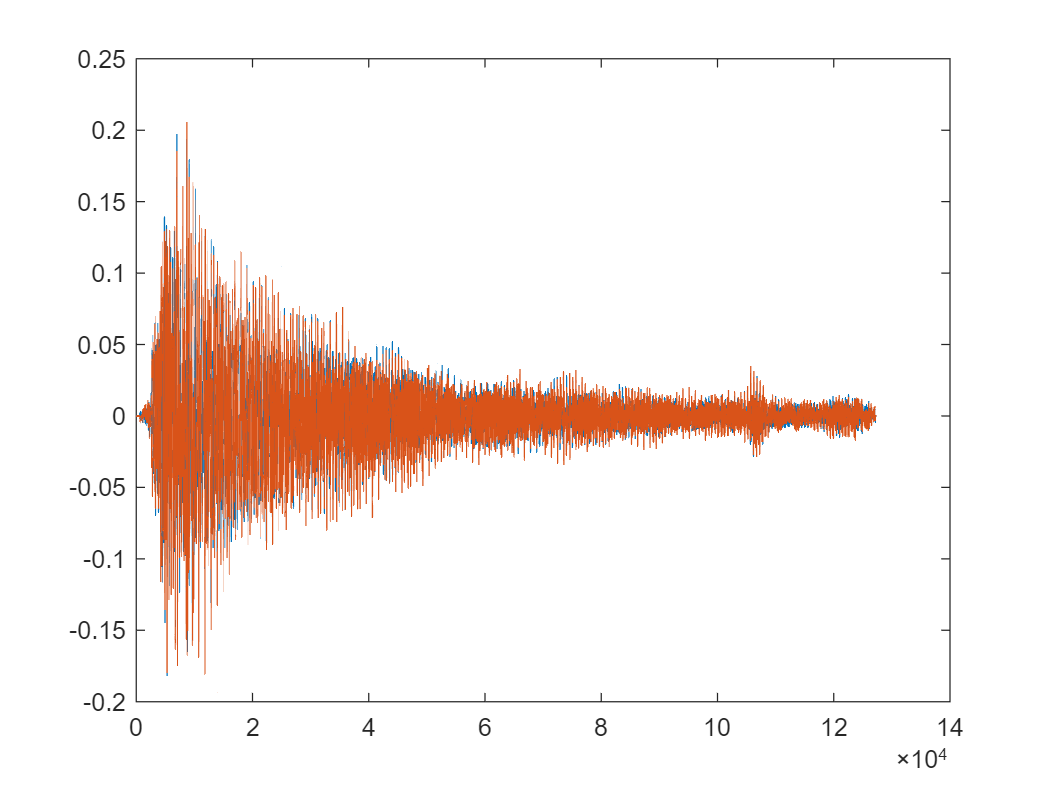

plot(y)

Pull a steady section of the signal. The time variable is computed from the sampling frequency.

yc = y(2e4:8e4,1);
tc = 1/Fs*(0:(length(yc)-1))';
L = tc(end)/2; % The domain is assumed to be 2L

Plot the steady section `yc` against `tc`.

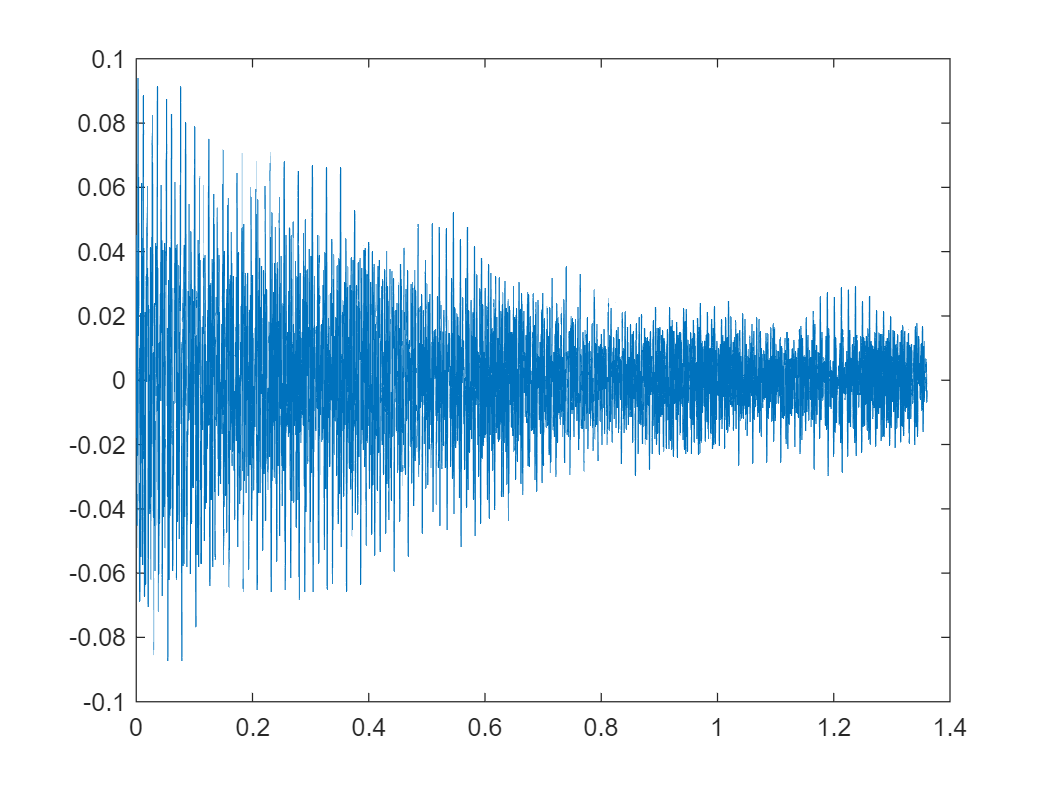

plot(tc,yc)

Compute the Fourier series of the signal

Nmodes = 6000; % Number of Fourier modes used in the estimation

a = zeros(1,Nmodes);
b = zeros(1,Nmodes);
a0 = 1/L*trapz(tc,yc);
for n = 1:Nmodes
    a(n) = 1/L*trapz(tc,cos(n*pi/L*tc).*yc);
    b(n) = 1/L*trapz(tc,sin(n*pi/L*tc).*yc);
end

Review the Fourier series coefficients

You can review the Fourier series coefficients by plotting them against $n$.

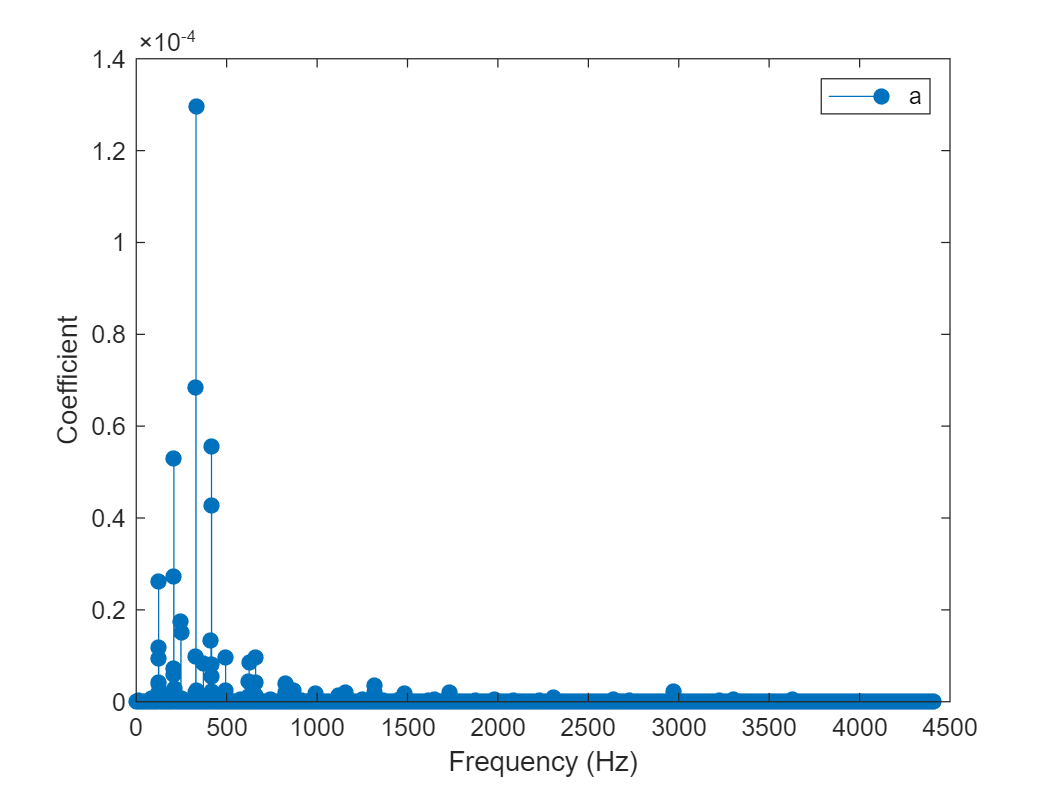

% Frequencies
f = (1:Nmodes)/(2*L);

stem(f,b.^2 + a.^2,"filled")
xlabel("Frequency (Hz)")
ylabel("Coefficient")
legend("a","b")

**Task.** What notes are in the chord? The frequencies of the notes are:


$$\text{\textbf{Octave 2}}
\\
\begin{array}{lr} 
\text{Note} & \text{ Hz} \\
C & 65.4 \\ 
C\# & 69.3 \\
D & 73.4 \\
D\# & 77.8\\
E & 82.4\\
F & 87.3 \\
F\# & 92.5 \\
G & 98.0\\
G\# & 103.8\\
A & 110.0\\
A\# & 116.5\\
B & 123.5\\
\end{array}$$
                
$$\text{\textbf{Octave 3}}
\\
\begin{array}{lr} 
\text{Note} & \text{ Hz} \\
C & 130.8 \\ 
C\# & 138.6 \\
D & 146.8\\
D\# & 155.6\\
E & 164.8\\
F & 174.6 \\
F\# & 185.0 \\
G & 196.0\\
G\# & 207.7\\
A & 220.0\\
A\# & 233.1\\
B & 246.9\\
\end{array}$$
                
$$\text{\textbf{Octave 4}}
\\
\begin{array}{lr} 
\text{Note} & \text{ Hz} \\
C & 261.6 \\ 
C\# & 277.2 \\
D & 293.7\\
D\# & 311.1\\
E & 329.6\\
F & 349.2\\
F\# & 370.0\\
G & 392.0\\
G\# & 415.3\\
A & 440.0\\
A\# & 466.2\\
B & 493.9\\
\end{array}$$


**Solution:**

The notes are B, G#, B, E

**Task.**

What is the cord? 

**Solution:**

E major

**Reflection.**

- What is the relationship between the same note at higher frequencies?

- Why do the notes occur more than once in the spectrum?

To review how well the Fourier series approximates the original function, compute the series sum.

% Sum the Fourier modes
t = tc;
ys = a0/2;
for n = 1:Nmodes
    ys = ys + a(n)*cos(n*pi/L*t) + b(n)*sin(n*pi/L*t);
end

Now plot it alongside the original function.

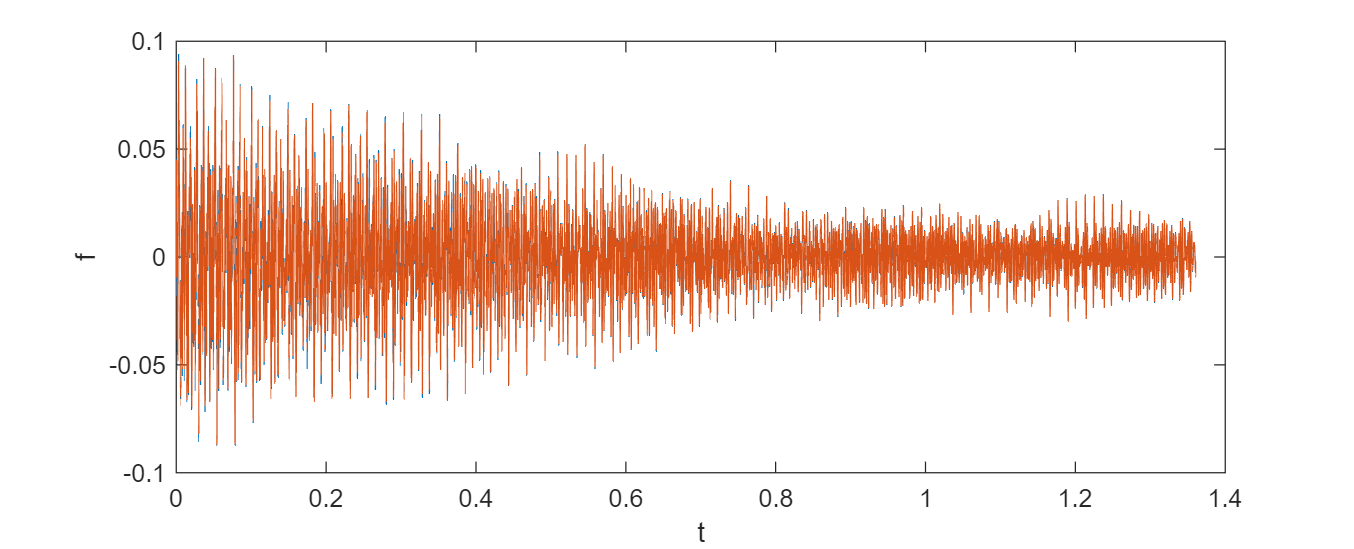

% Plot the result
figure("position",[1,1,800,325])
plot(tc,yc,t,ys)
xlabel("t")
ylabel("f")

Play the original sound

player = audioplayer(yc, Fs);
play(player);

Play the fourier series estimate

player = audioplayer(ys, Fs);
play(player);